# Lets explorethe classifications 

## Read in the  classification table


clsTab=import_classification_file('220420');

% set indices by the workflow of interest
right_wf=11990;

inds=find(clsTab.workflow_id==right_wf);


%% confirm that the subject id corresponds to a single subfind (1-to-1 relation)

inds=find(clsTab.workflow_id==11990);


subID=zeros(1,length(inds));

%isJelly=false(1,length(inds));
%subInfo=struct();
for i=1:length(inds)
    subID(i)=clsTab.subject_ids(inds(i));
    subInfo(i)=get_subject_info(clsTab.subject_data(inds(i)));
    qa(i)=parse_classification_info(clsTab.annotations(inds(i)));
    %isJelly(i)=isJellyfish_single(clsTab.annotations(inds(i)));
end




%  for i=1:length(inds)
%      subID(i)=clsTab.subject_ids(inds(i));
%      subInfo(i)=get_subject_info(clsTab.subject_data(inds(i)));
%
%  end

uID=unique(subID);

conf=true(length(uID),5);
for i=1:length(uID)
    
    ind2=find(subID==uID(i));
    
    conf2=true(length(ind2),5);
    for j=1:length(ind2)
        for k=1:5
            switch k
                case 1
                    conf2(j,k)= uID(i)==subInfo(ind2(j)).subjectID;
                    
                case 2
                    conf2(j,k)= strcmp(subInfo(ind2(1)).fullSimName,subInfo(ind2(j)).fullSimName);
                    
                case 3
                    conf2(j,k)= subInfo(ind2(1)).snap==subInfo(ind2(j)).snap;
                case 4
                    conf2(j,k)= subInfo(ind2(1)).hostID==subInfo(ind2(j)).hostID;
                case 5
                    conf2(j,k)= subInfo(ind2(1)).subfindID==subInfo(ind2(j)).subfindID;
            end
        end
    end
    
    for k=1:5
        conf(i,k)=all(conf2(:,k));
    end
    
end


% if all values are true than it is confirmed
all(conf(:,1))

ans = logical
   1


all(conf(:,2))

ans = logical
   1


all(conf(:,3))

ans = logical
   1


all(conf(:,4))

ans = logical
   1


all(conf(:,5))

ans = logical
   1


## Lets count how many objects in the workflow are from TNG50


% run over unique id's

uID=unique(subID);

for i=1:length(uID)
    
    ind2=find(subID==uID(i),1,'first');
    
    simName{i}=subInfo(ind2).simname;
end
simNameCat=categorical(simName);
countcats(simNameCat)

ans =          638           7        3469


categories(simNameCat)

ans = 3×1 cell array
    {'TNG100'}
    {'TNG300'}
    {'TNG50' }


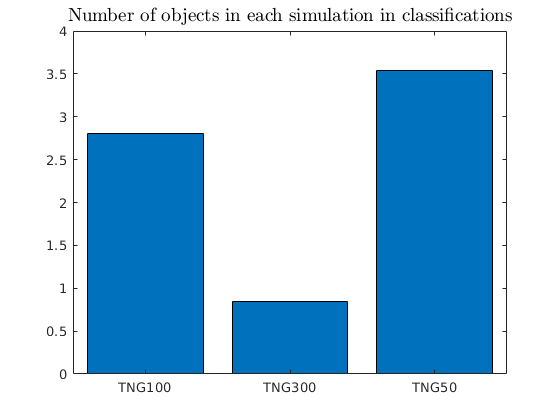


bar(categorical(categories(simNameCat)),log10(countcats(simNameCat)))
titlemine('Number of objects in each simulation in classifications');


countcats(simNameCat)

ans =          638           7        3469


categories(simNameCat)'

ans = 1×3 cell array
    {'TNG100'}    {'TNG300'}    {'TNG50'}


## Lets see what the questions are in the workflow

for i=1:length(qa)
    
    %ind2=find(subID==uID(i),1,'first');
    
    quests{i}=char(qa(i).question);
end
qCat=categorical(quests);
countcats(qCat)

ans =        18353          13          23


categories(qCat)

ans = 3×1 cell array
    {'Do you think that the galaxy at the center looks like a jellyfish ?'}
    {'Do you think that the galaxy at the center looks like a jellyfish?' }
    {'Do you think this galaxy you're watching is jellyfish galaxy?'      }


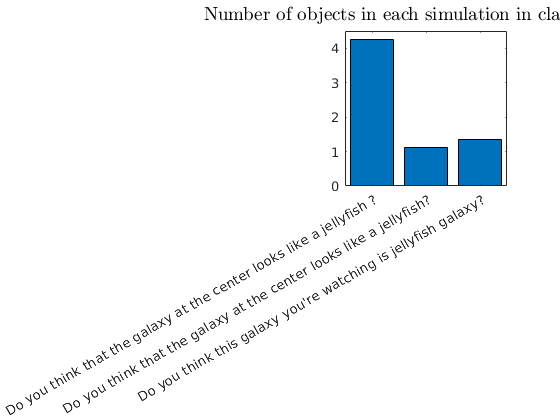


bar(categorical(categories(qCat)),log10(countcats(qCat)))
titlemine('Number of objects in each simulation in classifications');


%countcats(simNameCat)
%categories(simNameCat)'



cnt=0;
for i=1:length(qa)
    if strcmp(subInfo(i).simname,'TNG50')
        cnt=cnt+1;
        
        %ind2=find(subID==uID(i),1,'first');
        
        quests{cnt}=qa(i).question.cellstr;
    end
    
end
qCat=categorical(quests);

Error using categorical (line 357)
Could not find unique values in DATA using the UNIQUE function.

countcats(qCat)
categories(qCat)


bar(categorical(categories(qCat)),log10(countcats(qCat)))
titlemine('Number of objects in each simulation in classifications');

%countcats(simNameCat)
%categories(simNameCat)'

## lets generate a list of subject id's for TNG 50

subID_TNG50=[];

for i=1:length(uID)
    ind2=find(subID==uID(i),1,'first');
    if strcmp(subInfo(ind2).simname,'TNG50')
        subID_TNG50(end+1)=uID(i);
    end
end

fprintf('length of TNG50 id list: %i',length(subID_TNG50))

length of TNG50 id list: 3469

% do these id's show up in the other workflows?

indOthers=find(clsTab.workflow_id~=right_wf);

subId_2=clsTab.subject_ids(indOthers);
checks=false(size(subId_2));

for i=1:length(subId_2)
    checks(i)=any(subId_2(i)==uID);
end

sum(checks)

ans = 247


% Yes! must choose classifications from correct workflow





## How many classifications for each subject?




clsfCount=zeros(size(subID_TNG50));
for i=1:length(subID_TNG50)
    
    ind2=subID==subID_TNG50(i);
    clsfCount(i)=sum(ind2);
    
end


sum(clsfCount)

ans = 16511

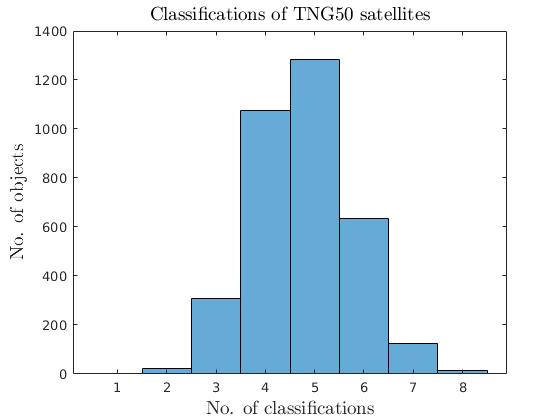


hs=histogram(clsfCount);

xlabelmine('No. of classifications');
ylabelmine('No. of objects');
titlemine('Classifications of TNG50 satellites');

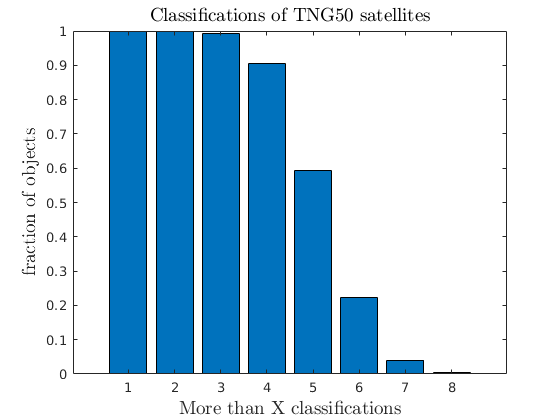



figure
ii=1:8;
bb=fliplr(cumsum(fliplr(hs.Values)));
bar(ii,bb/3469)

xlabelmine('More than X classifications');
ylabelmine('fraction of objects');
titlemine('Classifications of TNG50 satellites');

## lets run over all TNG50 relavent classifications and keep the things we want

inds=find(clsTab.workflow_id==11990);


%subID=zeros(1,length(inds));

%isJelly=false(1,length(inds));
%subInfo=struct();
cnt=0

cnt = 0

for i=1:length(inds)
    
    subj=clsTab.subject_ids(inds(i));
    
    if any(subID_TNG50==subj)
        cnt=cnt+1;
        subjID(cnt)=subj;
        subjInfo(cnt)=get_subject_info(clsTab.subject_data(inds(i)));
        inspector(cnt)=clsTab.user_name(inds(i));
        inspectorID(cnt)=clsTab.user_id(inds(i));
        isJelly(cnt)= isJellyfish_single(clsTab.annotations(inds(i)));
        
    end
    
end


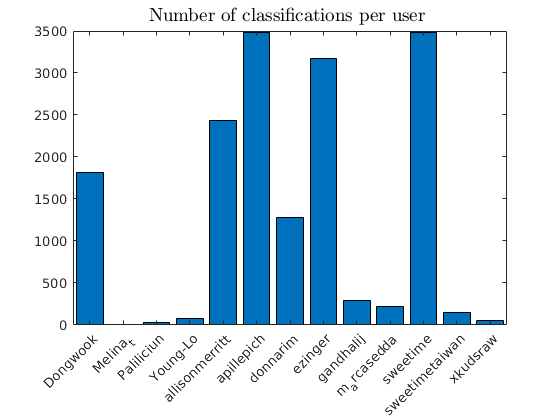


% how many classification per user

inspCat=categorical(inspector);
inspCounts=countcats(inspCat);
inspectors=categories(inspCat);

bar(categorical(inspectors),inspCounts)
titlemine('Number of classifications per user ');

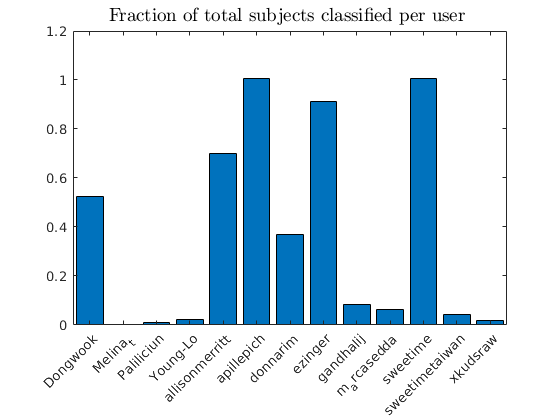


figure
bar(categorical(inspectors),inspCounts./3469)
titlemine('Fraction of total subjects classified per user ');

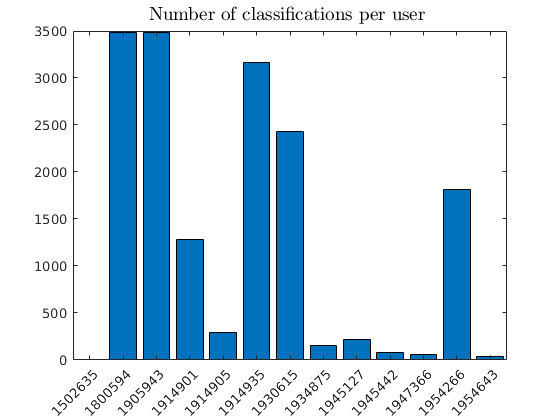




% how many 'expert classifications?
experts=inspectors([5:9 11]);
clsfCount=zeros(length(subID_TNG50),2);
jfCount=zeros(length(subID_TNG50),2);

for i=1:length(subID_TNG50)
    
    ind2=find(subjID==subID_TNG50(i));
    
    clsfCount(i,1)=length(ind2);
    jfCount(i,1)=sum(isJelly(ind2));
    
    
    for j=1:length(ind2)
        if any(strcmp(inspector(ind2(j)),experts))
            clsfCount(i,2)=clsfCount(i,2)+1;
            jfCount(i,2)=jfCount(i,2)+isJelly(ind2(j));
            
        end
    end
end

% AGAIN BUT WITH USER ID NUMBERS

inspCat2=categorical(inspectorID);
inspCounts2=countcats(inspCat2);
inspectors2=categories(inspCat2);

bar(categorical(inspectors2),inspCounts2)
titlemine('Number of classifications per user ');

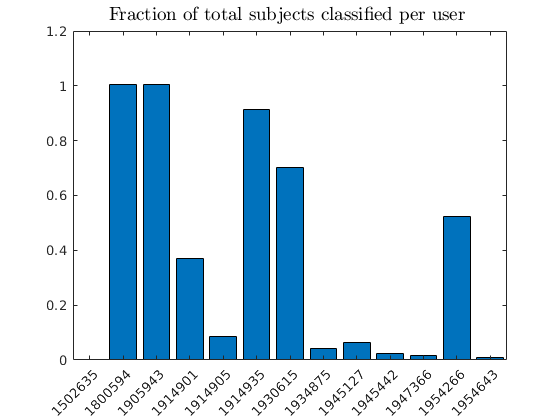


figure
bar(categorical(inspectors2),inspCounts2./3469)
titlemine('Fraction of total subjects classified per user ');




% how many 'expert classifications?
experts=inspectors([5:9 11]);
clsfCount=zeros(length(subID_TNG50),2);
jfCount=zeros(length(subID_TNG50),2);

for i=1:length(subID_TNG50)
    
    ind2=find(subjID==subID_TNG50(i));
    
    clsfCount(i,1)=length(ind2);
    jfCount(i,1)=sum(isJelly(ind2));
    
    
    for j=1:length(ind2)
        if any(strcmp(inspector(ind2(j)),experts))
            clsfCount(i,2)=clsfCount(i,2)+1;
            jfCount(i,2)=jfCount(i,2)+isJelly(ind2(j));
            
        end
    end
end




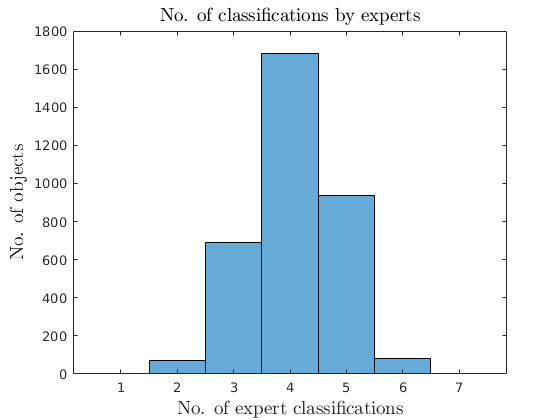

hs=histogram(clsfCount(:,2));
xlabelmine('No. of expert classifications');
ylabelmine('No. of objects');
titlemine('No. of classifications by experts');

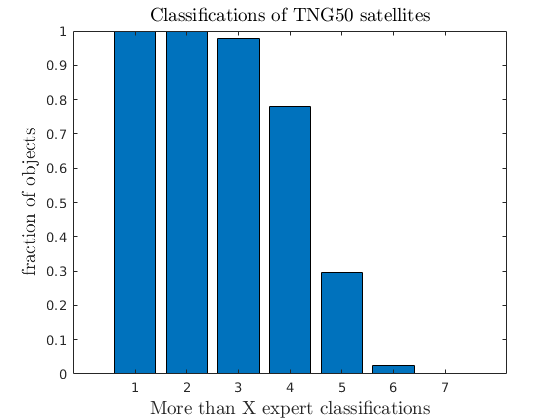



figure
ii=1:7;
bb=fliplr(cumsum(fliplr(hs.Values)));
bar(ii,bb/3469)

xlabelmine('More than X expert classifications');
ylabelmine('fraction of objects');
titlemine('Classifications of TNG50 satellites');

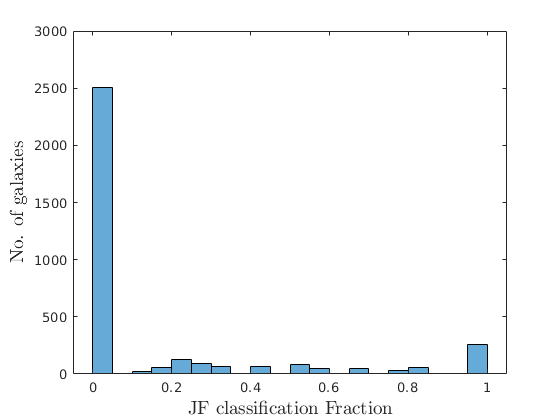

histogram(jfCount(:,1)./clsfCount(:,1))
xlabelmine('JF classification Fraction');
ylabelmine('No. of galaxies');

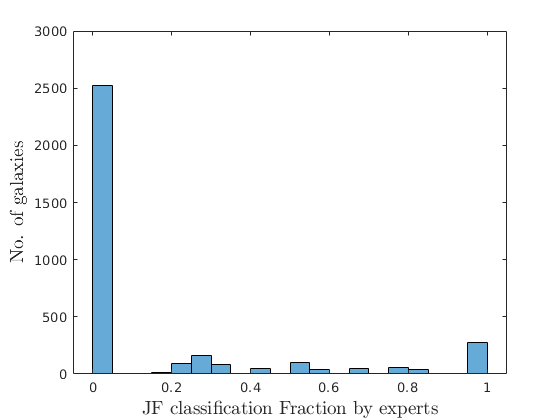



figure
histogram(jfCount(:,2)./clsfCount(:,2))
xlabelmine('JF classification Fraction by experts');
ylabelmine('No. of galaxies');



sum(jfCount(:,1)./clsfCount(:,1)>0.5)

ans = 451

sum(jfCount(:,2)./clsfCount(:,2)>0.9)

ans = 277

% figure out which snaps are shown

for i=1:length(subID_TNG50)
    
    ind2=find(subjID==subID_TNG50(i),1,"first");
    
    snaps(i)=subjInfo(ind2).snap;
    
end

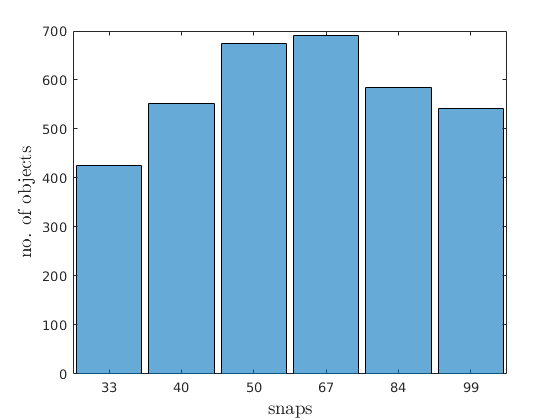


snapCat=categorical(snaps);

hss=histogram(snapCat);
xlabelmine('snaps');
ylabelmine('no. of objects');


% and in redshift

%snapCat=categorical(illustris.utils.snap2redshift(snaps));
%figure
%histogram(snapCat,)
%xlabelmine('snaps');
%ylabelmine('no. of objects');





## generate subfind id list broken up into snapshots

subfindList_33=zeros(425,3);
subfindList_40=zeros(533,3);
subfindList_50=zeros(674,3);
subfindList_67=zeros(690,3);
subfindList_84=zeros(585,3);
subfindList_99=zeros(542,3);

cnt33=0;
cnt40=0;
cnt50=0;
cnt67=0;
cnt84=0;
cnt99=0;


jfscore(:,1)=jfCount(:,1)./clsfCount(:,1);
jfscore(:,2)=jfCount(:,2)./clsfCount(:,2);

for i=1:length(subID_TNG50)
    ind2=find(subjID==subID_TNG50(i),1,"first");
    
    snap=subjInfo(ind2).snap;
    
    switch snap
        case 33
            cnt33=cnt33+1;
            subfindList_33(cnt33,1)=subjInfo(ind2).subfindID;
            subfindList_33(cnt33,2)=subjInfo(ind2).hostID;
            subfindList_33(cnt33,3)=subID_TNG50(i);
        case 40
            cnt40=cnt40+1;
            subfindList_40(cnt40,1)=subjInfo(ind2).subfindID;
            subfindList_40(cnt40,2)=subjInfo(ind2).hostID;
            subfindList_40(cnt40,3)=subID_TNG50(i);
        case 50
            cnt50=cnt50+1;
            subfindList_50(cnt50,1)=subjInfo(ind2).subfindID;
            subfindList_50(cnt50,2)=subjInfo(ind2).hostID;
            subfindList_50(cnt50,3)=subID_TNG50(i);
        case 67
            cnt67=cnt67+1;
            subfindList_67(cnt67,1)=subjInfo(ind2).subfindID;
            subfindList_67(cnt67,2)=subjInfo(ind2).hostID;
            subfindList_67(cnt67,3)=subID_TNG50(i);
        case 84
            cnt84=cnt84+1;
            subfindList_84(cnt84,1)=subjInfo(ind2).subfindID;
            subfindList_84(cnt84,2)=subjInfo(ind2).hostID;
            subfindList_84(cnt84,3)=subID_TNG50(i);
        case 99
            cnt99=cnt99+1;
            subfindList_99(cnt99,1)=subjInfo(ind2).subfindID;
            subfindList_99(cnt99,2)=subjInfo(ind2).hostID;
            subfindList_99(cnt99,3)=subID_TNG50(i);
 
    end
            
end

    










## plot host mass

jfscore(:,1)=jfCount(:,1)./clsfCount(:,1);
jfscore(:,2)=jfCount(:,2)./clsfCount(:,2);

cnt=0;

for i=1:length(subID_TNG50)
    ind2=find(subjID==subID_TNG50(i),1,"first");
    
    
    if jfscore(i,1)>0.8
        cnt=cnt+1;
    
        snap=subjInfo(ind2).snap;
        
        switch snap
            case 33
            id=find(subID_TNG50(i)==subfindList_33(:,3));
               
            hostmass(cnt)=log10(mass33(id,2));
            
        case 40
           id=find(subID_TNG50(i)==subfindList_40(:,3));
               
            hostmass(cnt)=log10(mass40(id,2)); 
        case 50
            id=find(subID_TNG50(i)==subfindList_50(:,3));
               
            hostmass(cnt)=log10(mass50(id,2));
        case 67
           id=find(subID_TNG50(i)==subfindList_67(:,3));
               
            hostmass(cnt)=log10(mass67(id,2));
        case 84
           id=find(subID_TNG50(i)==subfindList_84(:,3));
               
            hostmass(cnt)=log10(mass84(id,2));
        case 99
            id=find(subID_TNG50(i)==subfindList_99(:,3));
               
            hostmass(cnt)=log10(mass99(id,2));
 
    end
            
    end
    
end


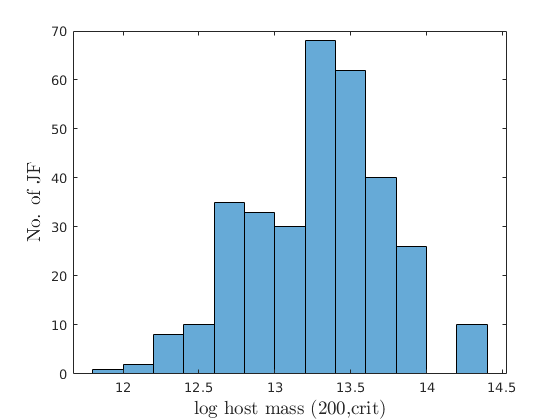


hs=histogram(hostmass(hostmass>0));

xlabelmine('log host mass (200,crit)');
ylabelmine('No. of JF');